# Solving Differential Equations

We first consider the predator-prey model with the following parameters:

a = 1.5;
b = 1.1;
c = 2.5;
d = 1.4;
k = 0;

We want to solve the differential equations for $t\in \left\lbrack 0,30\right\rbrack$, given the initial condition $x\left(0\right)=\left\lbrack 5;1\right\rbrack$

tspan = [0 30];
myode = @(t,x) flow_field(x,a,b,c,d,k);

[t,x] = ode45(myode,tspan,[5 1]);

Note how we defined `myode `as a function handle that depends on the variables (`t,x)`. This is the standard format expected by `ode45`, and we need to use it even if the differential equation does not explicitly depend on `t`.

## Dynamic Response

We can now plot $x_1 \left(t\right)$, i.e. the predator population dynamics, and $x_2 \left(t\right)$, i.e. the prey population dynamics

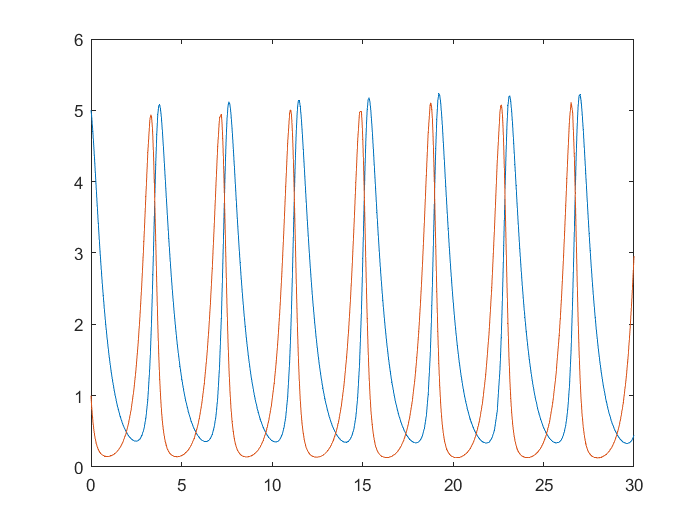

plot(t,x(:,1),t,x(:,2))

## Trajectories

It's also useful to plot the trajectories of the system in the so-called phase plane $\left(x_1 ,x_2 \right)$

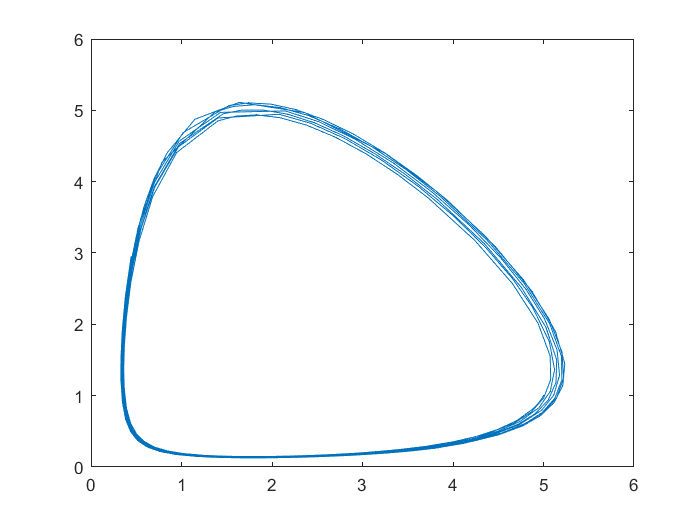

plot(x(:,1),x(:,2))

Note that we'll get different periodic orbits depending on our initial conditions.

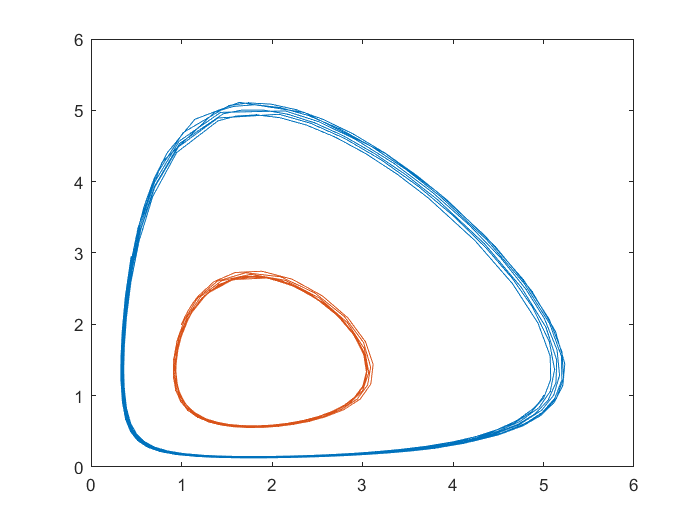

[t,x2] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[1 2]);

plot(x(:,1),x(:,2))
hold on
plot(x2(:,1),x2(:,2))
hold off

## Equilibrium Points

An equilibrium point is where the flow field is equal to zero. To find an equilibrium point of the system, we need to solve


$$\left\lbrace \begin{array}{ll}
{\dot{x} }_1 =0 & \\
{\dot{x} }_2 =0 & 
\end{array}\right.$$


We can do so using the `fsolve` function, given an initial guess $x_i =\left\lbrack 1;\;1\right\rbrack$

x_eq = fsolve(@(x) flow_field(x,a,b,c,d,k),[1,1]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


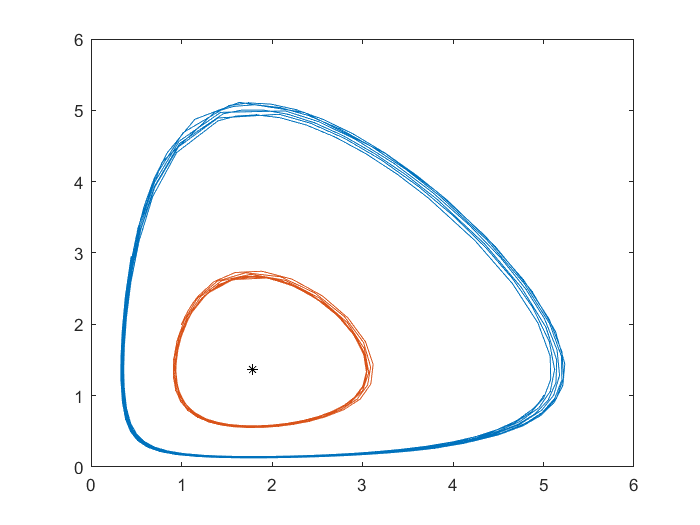

plot(x(:,1),x(:,2))
hold on
plot(x2(:,1),x2(:,2))
plot(x_eq(1),x_eq(2),'k*')
hold off

In this case, the equilibrium point is stable.

Note that, for a different initial guess, we'll get a different equilibrium point, which captures different behavoirs

x_eq2 = fsolve(@(x) flow_field(x,a,b,c,d,k),[1,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Here, we get the origin, i.e. no predators and no prey.

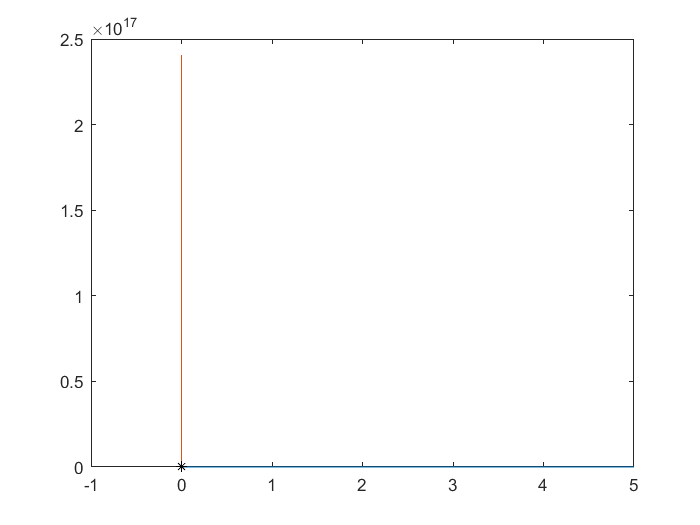

[t,x3] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[5 0]);         % Only Predators
[t,x4] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[0 1e-14]);     % Only Prey

plot(x3(:,1),x3(:,2))
hold on
plot(x4(:,1),x4(:,2))
plot(x_eq2(1),x_eq2(2),'k*')
hold off

If you have only predators, their population will exponentially decay to zero. If you have only prey, their population will grow exponentially. 

This equilibrium point is unstable.

## Flow Fields

If we wish to plot the flow field, we need to compute the vector


$$\left\lbrack \begin{array}{c}
U\\
V
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-a\;x+b\;x\;y\\
c\left(1-k\;y\right)\;y-d\;x\;y
\end{array}\right\rbrack$$


We'll do so by creating a grix for $x\in \left\lbrack 0,5\right\rbrack$ and$y\in \left\lbrack 0,5\right\rbrack$

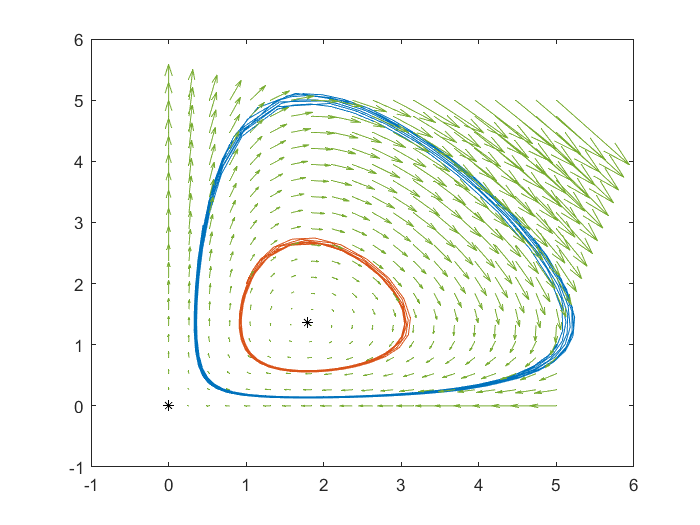

[X,Y] = meshgrid(linspace(0,5,20),linspace(0,5,20));
U = -a*X+b*X.*Y;
V = c*(1-k*Y).*Y-d*X.*Y;

plot(x(:,1),x(:,2))
hold on
plot(x2(:,1),x2(:,2))
plot(x_eq(1),x_eq(2),'k*')
plot(x_eq2(1),x_eq2(2),'k*')
quiver(X,Y,U,V,4)
hold off

## Case $k\not= 0$

In the case $k\not= 0$, the system has three equilibrium points, one of which is asymptotically stable (the other two are unstable).

k = 0.5;

% Solve for different initial conditions
[t,x ] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[5 1]);
[t,x2] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[1 2]);
[t,x3] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[2 3]);
[t,x4] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[4 0]);
[t,x5] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[0 1]);
[t,x6] = ode45(@(t,x) flow_field(x,a,b,c,d,k),tspan,[0 3]);

% Find the different equilibrium points
x_eq  = fsolve(@(x) flow_field(x,a,b,c,d,k),[1,1]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_eq2 = fsolve(@(x) flow_field(x,a,b,c,d,k),[1,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_eq3 = fsolve(@(x) flow_field(x,a,b,c,d,k),[2,4]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


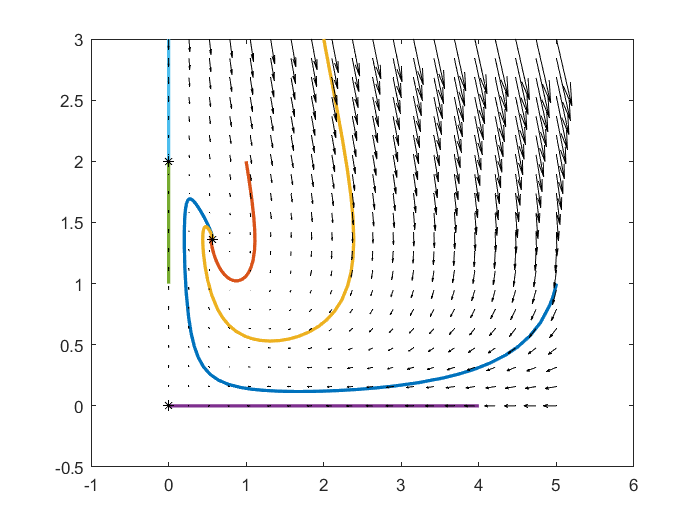


% Compute Flow Field
[X,Y] = meshgrid(linspace(0,5,20),linspace(0,3,20));
U = -a*X+b*X.*Y;
V = c*(1-k*Y).*Y-d*X.*Y;

% Plot everything
plot(x(:,1),x(:,2),'LineWidth',2)
hold on
plot(x2(:,1),x2(:,2),'LineWidth',2)
plot(x3(:,1),x3(:,2),'LineWidth',2)
plot(x4(:,1),x4(:,2),'LineWidth',2)
plot(x5(:,1),x5(:,2),'LineWidth',2)
plot(x6(:,1),x6(:,2),'LineWidth',2)
plot(x_eq(1),x_eq(2),'k*')
plot(x_eq2(1),x_eq2(2),'k*')
plot(x_eq3(1),x_eq3(2),'k*')
quiver(X,Y,U,V,2,'k')
hold off

Note that I get different equilibrium points depending on the initial conditions I give to my solver.

# Lotka-Volterra Equation

Also known as the predator-prey model, it capures the population dynamics of a predator ($x_1$) and prey ($x_2$) system.


$$\left\lbrace \begin{array}{ll}
{\dot{x} }_1 =-a\;x_1 +b\;x_1 x_2  & \\
{\dot{x} }_2 =c\left(1-{\mathrm{kx}}_2 \right)\;x_2 -d\;x_1 x_2  & 
\end{array}\right.$$


function dx = flow_field(x,a,b,c,d,k)

dx = [ -a*x(1)+b*x(1)*x(2)
       c*(1-k*x(2))*x(2)-d*x(1)*x(2) ];

end